J = 0.01;
b = 0.1;
K = .23;
R = 27.72;
L = 0.015827;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2)

P_motor =
 
                0.23
  --------------------------------
  0.0001583 s^2 + 0.2788 s + 2.825
 
Continuous-time transfer function.



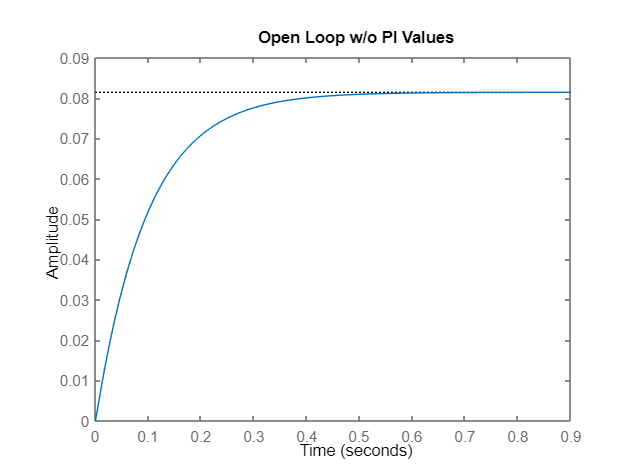

step(P_motor)
title("Open Loop w/o PI Values")


%%num = 0.23;
%%den = [0.000158277 0.27885477 2.8556];
%%Gp = tf(num,den);
J = 0.01;
b = 0.1;
K = .23;
R = 27.72;
L = 0.015827;
s = tf('s');
Gp = K/((J*s+b)*(L*s+R)+K^2)

Gp =
 
                0.23
  --------------------------------
  0.0001583 s^2 + 0.2788 s + 2.825
 
Continuous-time transfer function.



Gc = pid(3,5);
G1 = Gp*Gc;
G = feedback(G1,1);
step(G)
stepinfo(G)

ans = struct with fields:
         RiseTime: 6.2095
    TransientTime: 11.0506
     SettlingTime: 11.0506
      SettlingMin: 0.9001
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 24.6557


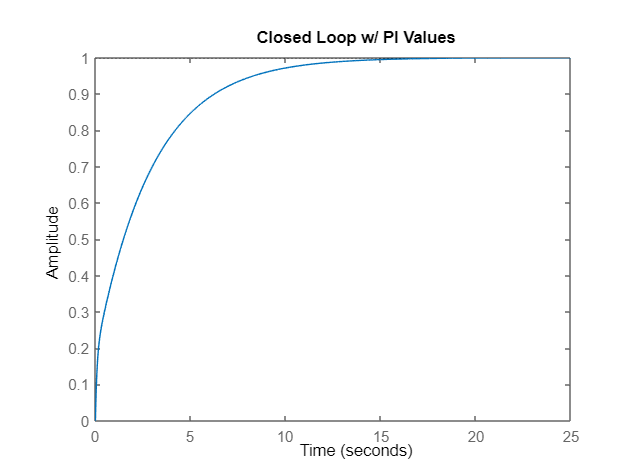

title("Closed Loop w/ PI Values")


num = 0.23;
den = [0.000158277 0.27885477 2.8556];
Gp = tf(num,den);
Gc = 1;
G1 = Gp*Gc;
G = feedback(G1,1);
step(G)
stepinfo(G)

ans = struct with fields:
         RiseTime: 0.1973
    TransientTime: 0.3519
     SettlingTime: 0.3519
      SettlingMin: 0.0674
      SettlingMax: 0.0745
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0745
         PeakTime: 0.9470


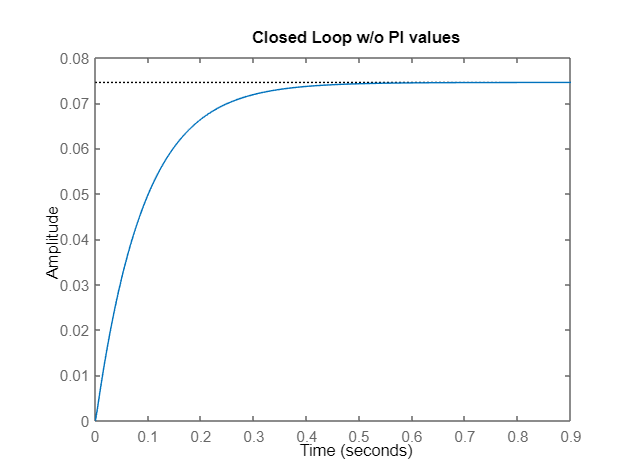

title("Closed Loop w/o PI values")